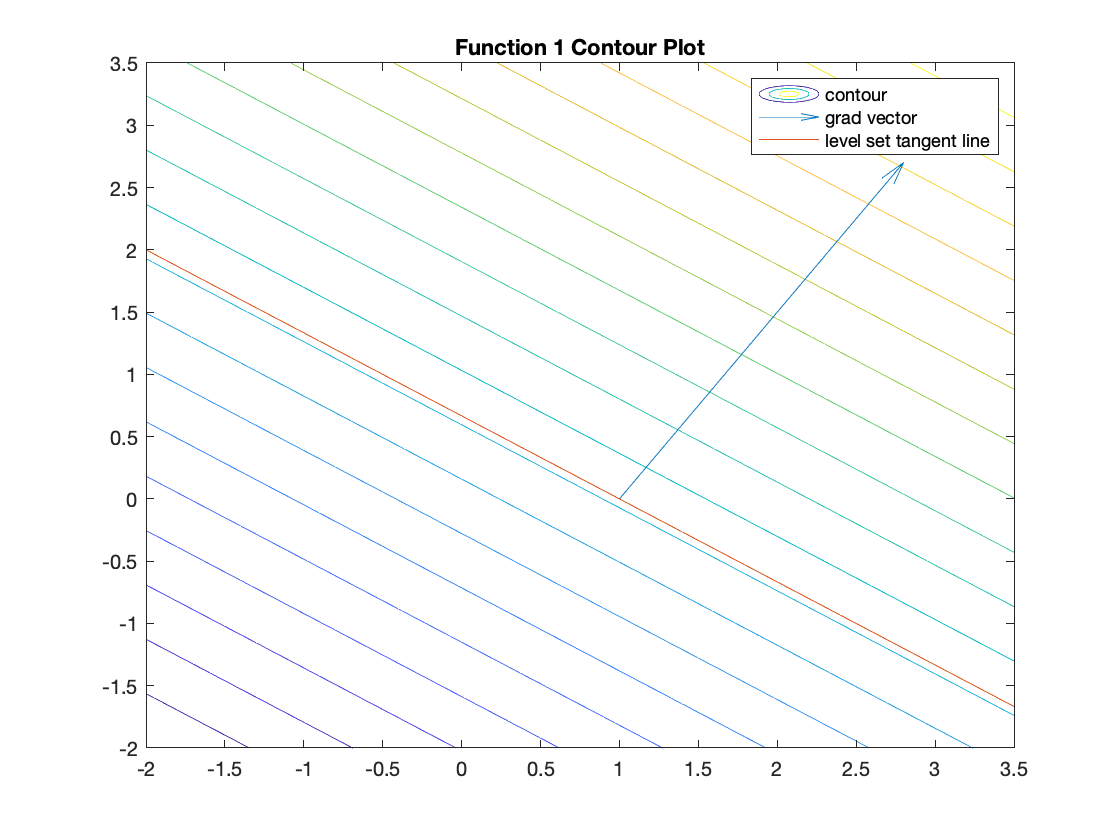

% PART A: Done in Notion in main 'answers' doc.
% PART B: Contour plots

% Figuring out meshgrid, contour

x = -2:.1:3.5;
y = -2:.1:3.5;

x0 = 1;
y0 = 0;

[X, Y] = meshgrid(x, y);

f1 = 2*X+3*Y+1;
f2 = X.^2 + Y.^2 - X.*Y - 5;
f3 = (X-5).*cos(Y-5)-(Y-5).*sin(X-5);

% FUNCTION 1

contour(X, Y, f1, 20);
% How to add in the gradient arrow.

grad_f_x = 2;
grad_f_y = 3;

hold on
quiver(x0, y0, grad_f_x, grad_f_y); % Replace last two with x, y component of gradient.
hold off

% How to add in line.
m = (-1*grad_f_x)/grad_f_y;

y = m*(x-x0)+y0; % replace with point slope form for tangent line.
hold on
plot(x, y);
hold off

title('Function 1 Contour Plot');
legend('contour', 'grad vector', 'level set tangent line');

xlim([-2 3.5])
ylim([-2 3.5])

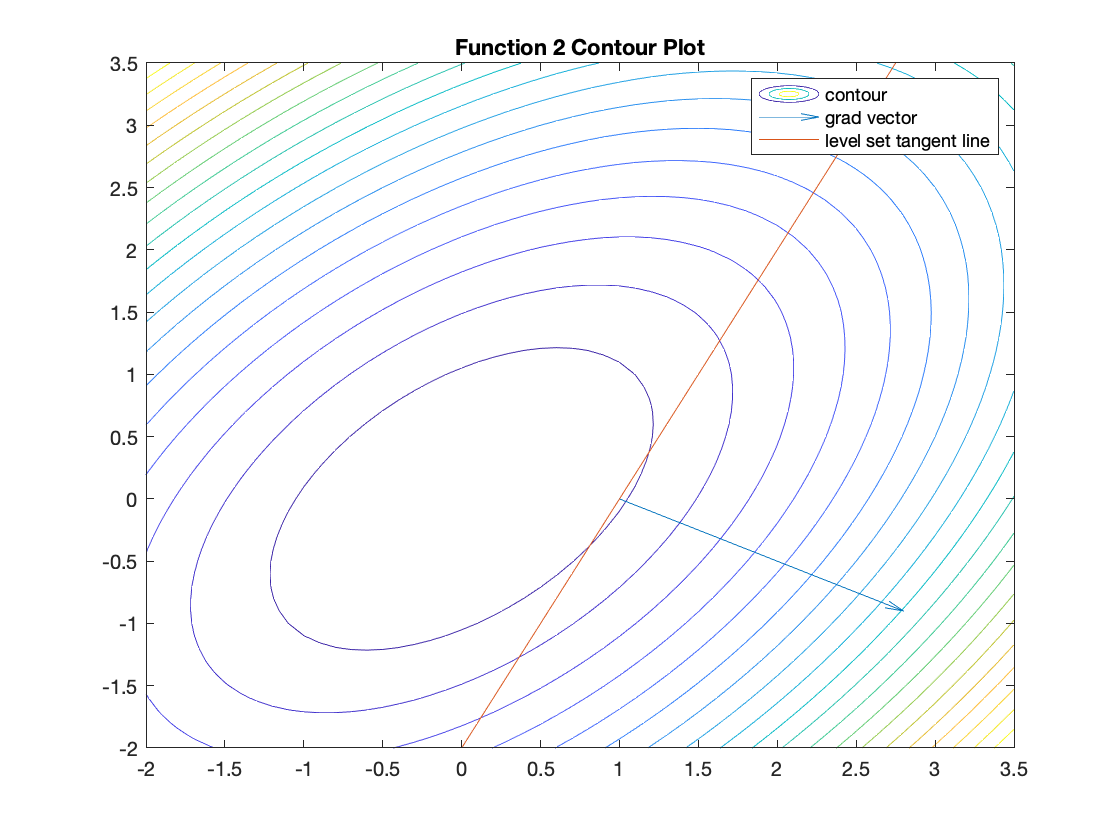

% FUNCTION 2

contour(X, Y, f2, 20);
% How to add in the gradient arrow.

grad_f_x = 2;
grad_f_y = -1;

hold on
quiver(x0, y0, grad_f_x, grad_f_y); % Replace last two with x, y component of gradient.
hold off

% How to add in line.
m = (-1*grad_f_x)/grad_f_y;

y = m*(x-x0)+y0; % replace with point slope form for tangent line.
hold on
plot(x, y);
hold off

title('Function 2 Contour Plot');
legend('contour', 'grad vector', 'level set tangent line');

xlim([-2 3.5])
ylim([-2 3.5])

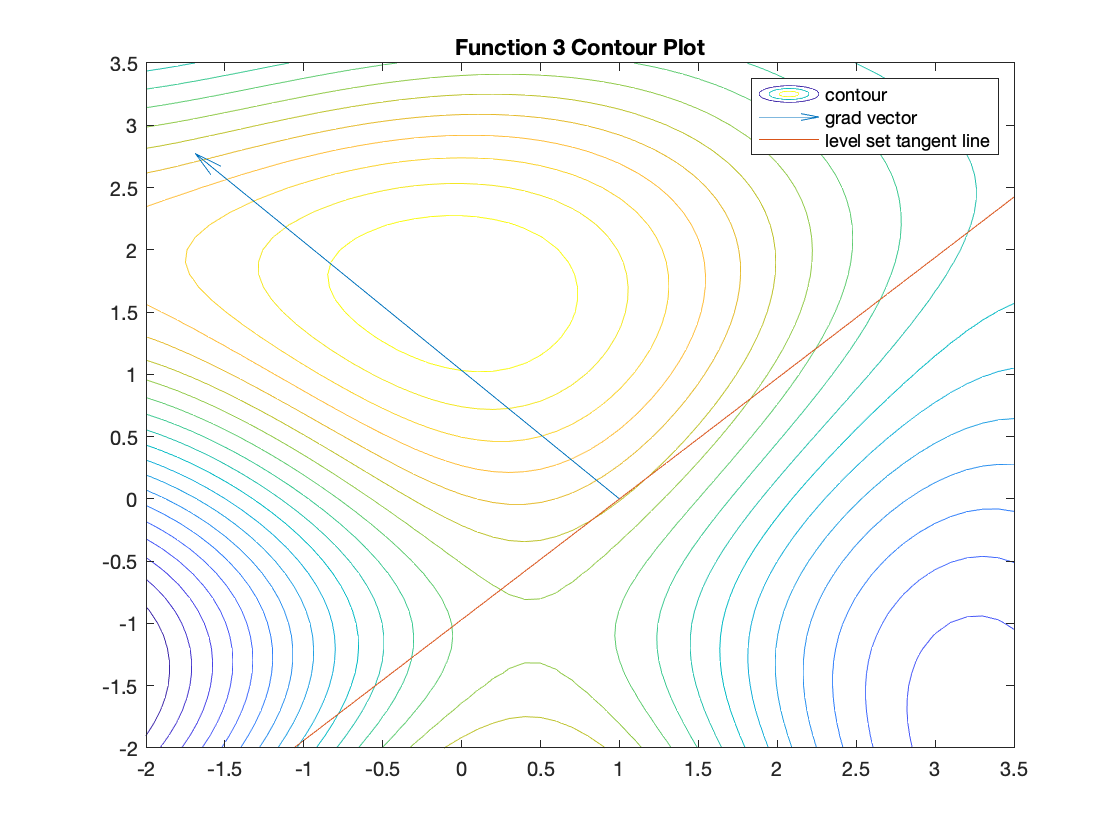

% FUNCTION 3

contour(X, Y, f3, 20);
% How to add in the gradient arrow.

grad_f_x = cos(-5)+5*cos(-4);
grad_f_y = 4*sin(-5) - sin(-4);

hold on
quiver(x0, y0, grad_f_x, grad_f_y); % Replace last two with x, y component of gradient.
hold off

% How to add in line.
m = (-1*grad_f_x)/grad_f_y;

y = m*(x-x0)+y0; % replace with point slope form for tangent line.
hold on
plot(x, y);
hold off

title('Function 3 Contour Plot');
legend('contour', 'grad vector', 'level set tangent line');

xlim([-2 3.5])
ylim([-2 3.5])

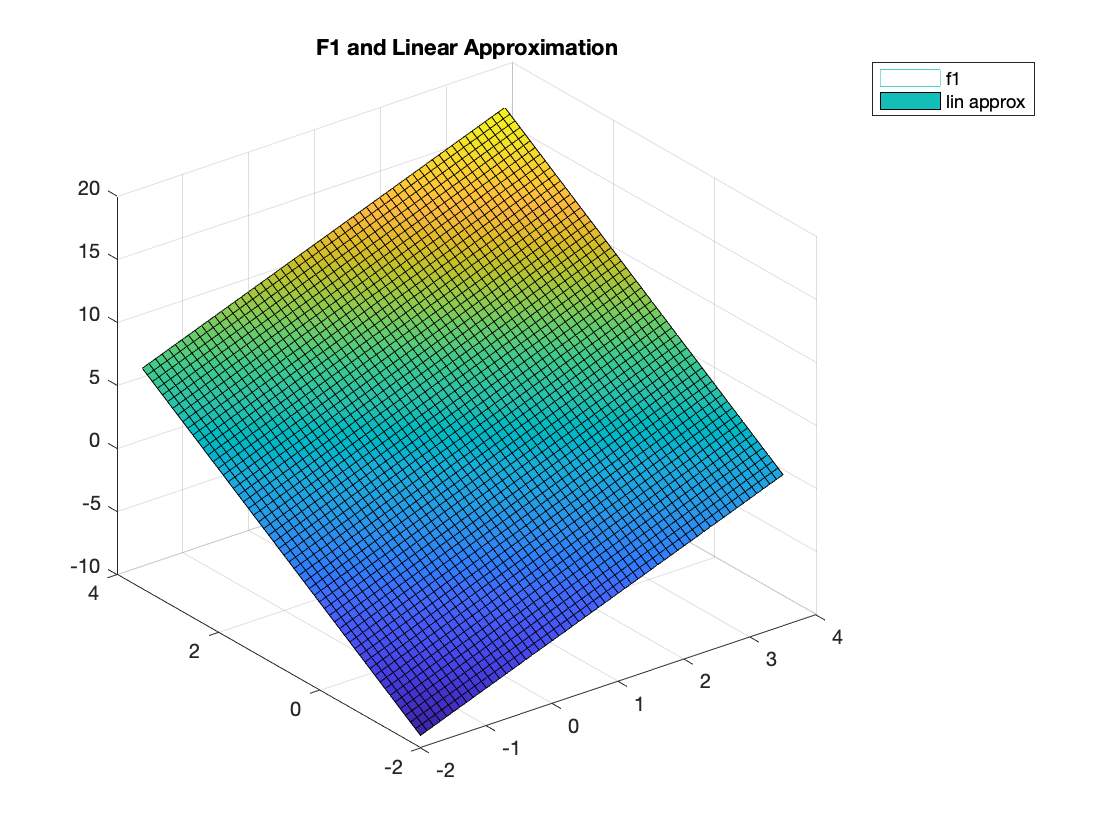

% Part C: 3D Plots with Linear Approximation at (1, 0)


x = -2:.1:3.5;
y = -2:.1:3.5;

% f1: metadata
x0 = 1;
y0 = 0;

[X, Y] = meshgrid(x, y);

f1 = 2*X+3*Y+1;
f2 = X.^2 + Y.^2 - X.*Y - 5;
f3 = (X-5).*cos(Y-5)-(Y-5).*sin(X-5);

% FUNCTION 1
grad_f_x = 2;
grad_f_y = 3;

z = 2*x0 + 3*y0 + 1;
lin_approx = get_affine_approx(grad_f_x, grad_f_y, -1, x0, y0, z, X, Y);

mesh(X, Y, f1);hold on
surf(X, Y, lin_approx);
legend('f1', 'lin approx');
title('F1 and Linear Approximation')
hold off

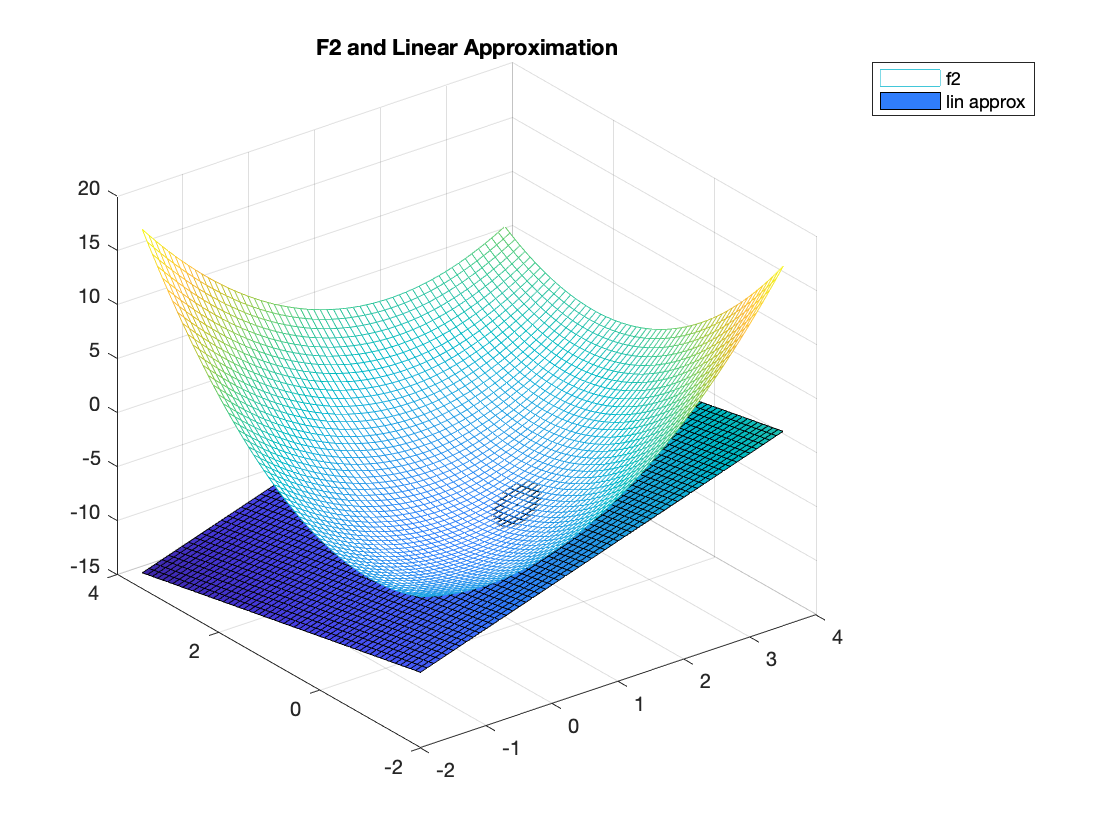


% FUNCTION 2
grad_f_x = 2;
grad_f_y = -1;

z = x0^2 + y0^2 - x0*y0 - 5;
lin_approx = get_affine_approx(grad_f_x, grad_f_y, -1, x0, y0, z, X, Y);

mesh(X, Y, f2);hold on
surf(X, Y, lin_approx);
legend('f2', 'lin approx');
title('F2 and Linear Approximation')
hold off

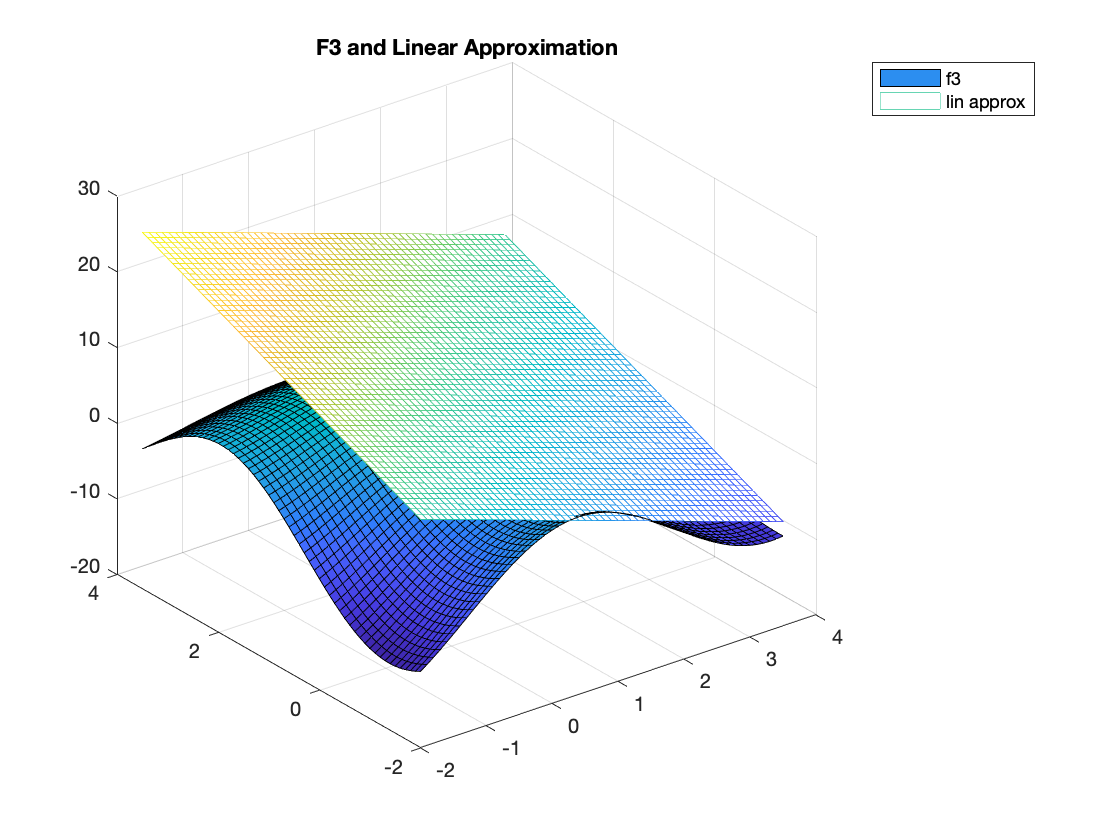


% FUNCTION 3
grad_f_x = cos(-5)+5*cos(-4);
grad_f_y = 4*sin(-5) - sin(-4);

z = (x0-5).*cos(x0-5)-(y0-5).*sin(y0-5);
lin_approx = get_affine_approx(grad_f_x, grad_f_y, -1, x0, y0, z, X, Y);

surf(X, Y, f3);hold on
mesh(X, Y, lin_approx);
legend('f3', 'lin approx');
title('F3 and Linear Approximation')

hold off

function [pprox] = get_affine_approx(a, b, c, x, y, z, X, Y)
    d = a*x + b*y + c*z;
    pprox = (-1/c)*(a*X + b*Y) + d/c;
end

